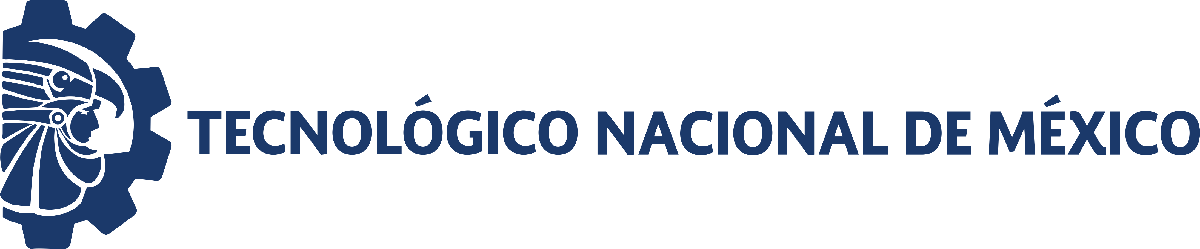                                 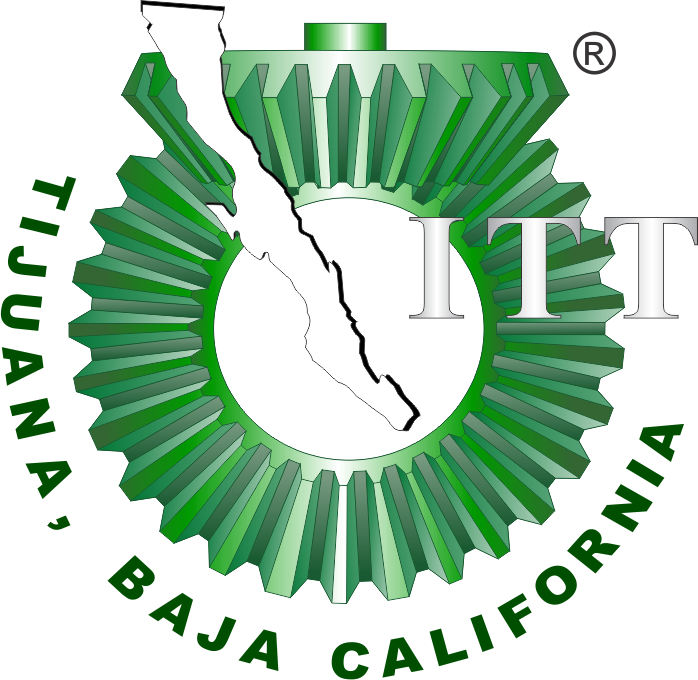

# Práctica cero: Mecánica pulmonar

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

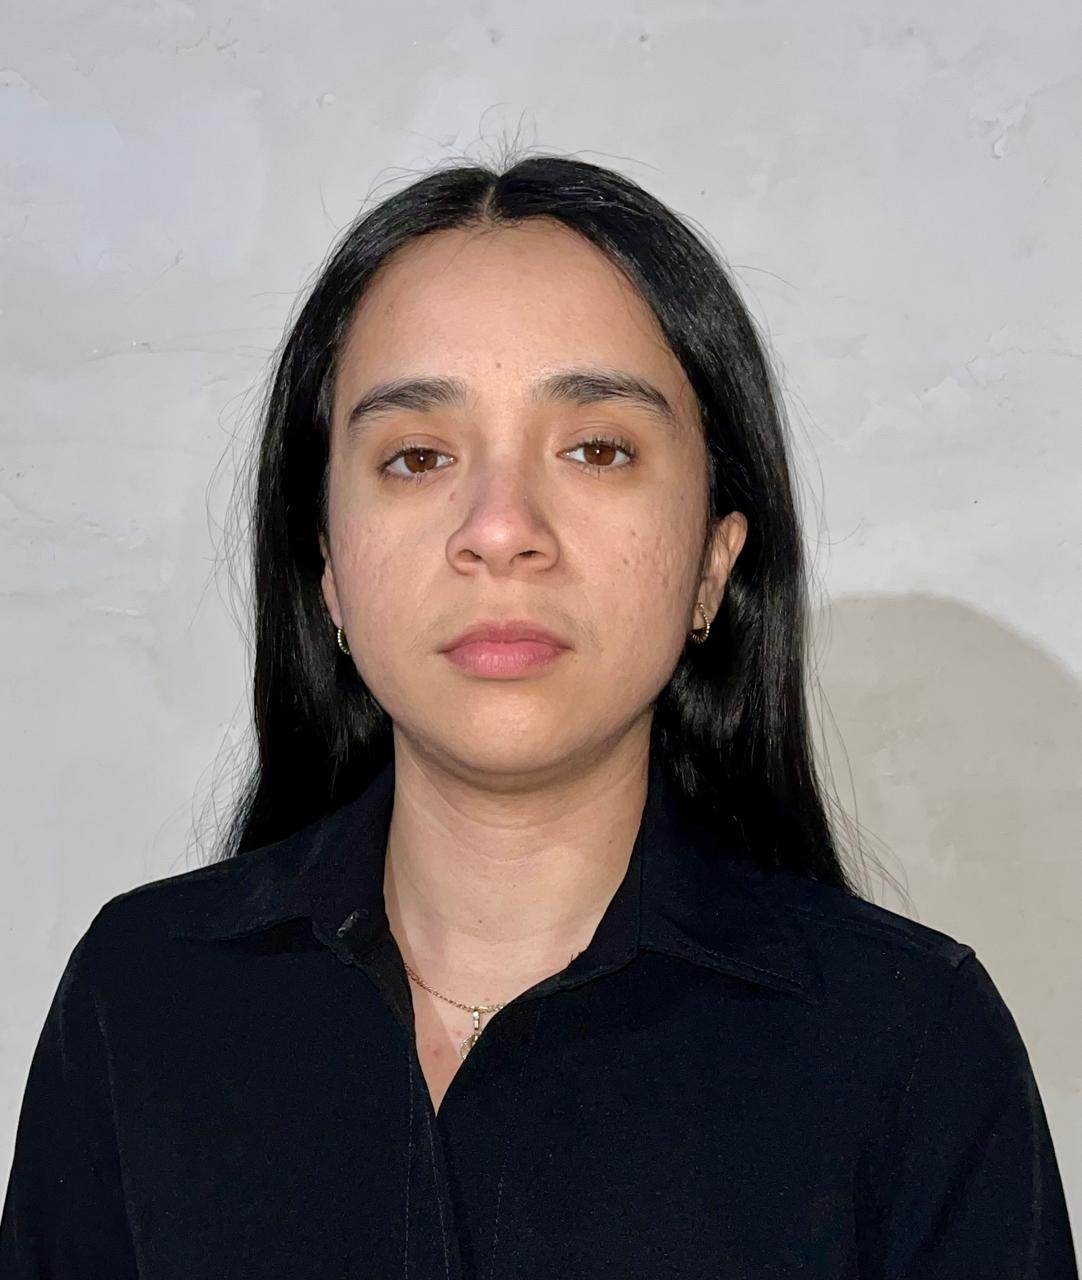

Nombre del alumno: **Adriana Estefania Bañuelos Ocampo**

Número de control: **23210694**

Correo institucional: **L23210694@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; close all; warning('off','all')
tend = '10';
file= 'Sistema';
open_system(file);
parameters.StopTime=tend;
parameters.Solver='ode15s';
parameters.MaxStep='1E-3';
set_param('Sistema/PA0(t)','VectorFormat','1-D array');

## Respuesta al escalón

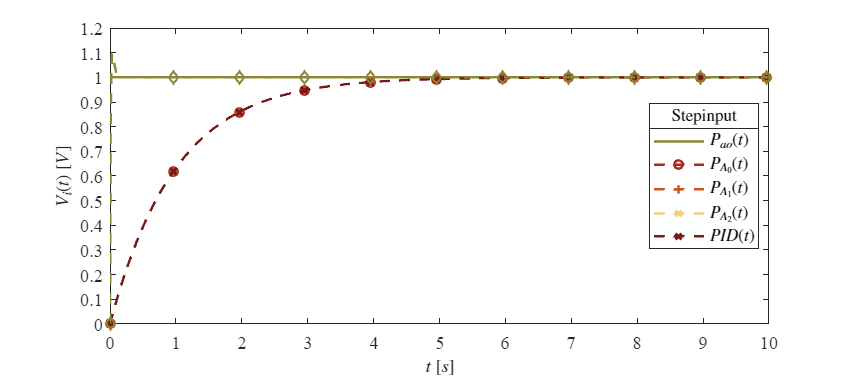

Signal='Step';
set_param('Sistema/S1','sw','1');
set_param('Sistema/Pao(t)','sw','1');
x1=sim(file,parameters);
plotsignals(x1.t,x1.Pao,x1.P0,x1.P1,x1.P2,x1.PID,Signal)

## Respuesta al impulso

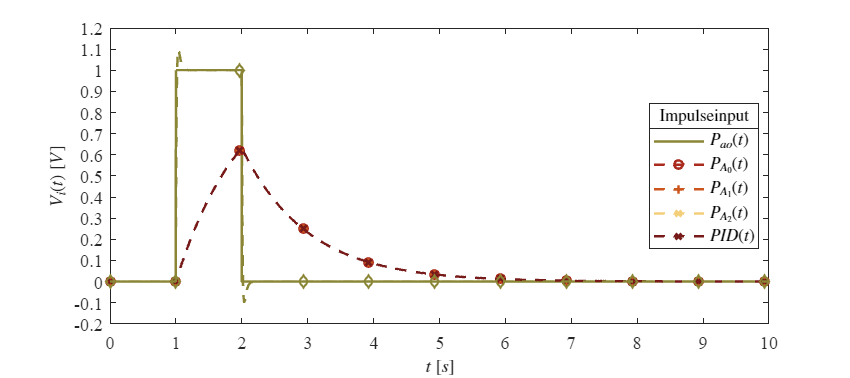

Signal='Impulse';
set_param('Sistema/S1','sw','0');
set_param('Sistema/Pao(t)','sw','1');
x2=sim(file,parameters);
plotsignals(x2.t,x2.Pao,x2.P0,x2.P1,x2.P2,x2.PID,Signal)

## Respuesta a la rampa

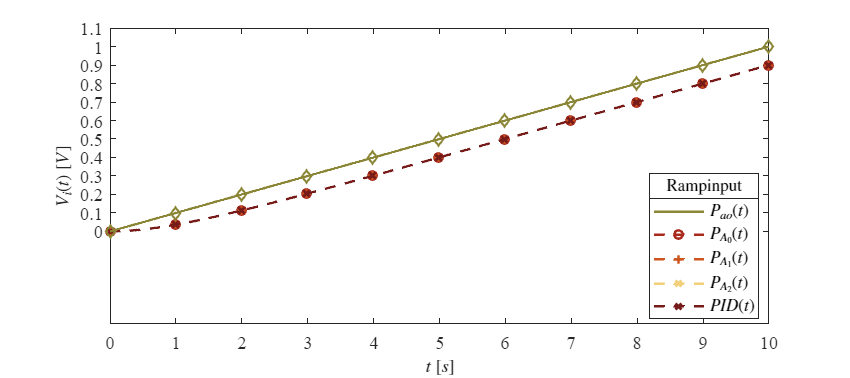

Signal='Ramp';
set_param('Sistema/S2','sw','1');
set_param('Sistema/Pao(t)','sw','0');
x3=sim(file,parameters);
plotsignals(x3.t,x3.Pao,x3.P0,x3.P1,x3.P2,x3.PID,Signal)

## Respuesta a la función sinusoidal

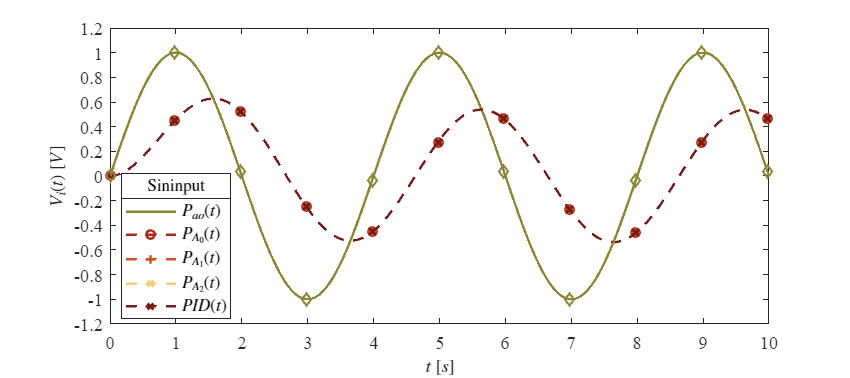

Signal='Sin';
set_param('Sistema/S2','sw','0');
set_param('Sistema/Pao(t)','sw','0');
x4=sim(file,parameters);
plotsignals(x4.t,x4.Pao,x4.P0,x4.P1,x4.P2,x4.PID,Signal)

## Función: Respuestas a las señales 

function plotsignals(t,Pao,P0,P1,P2,PID,Signal)
    set (figure(),'Color','w')
    set(gcf,'units','centimeters','position',[1,1,18,8])
    set(gca,'FontName','Times New Roman','Fontsize',11)
    hold on; grid off;box on
    
    colors = [138, 134, 53;
              170, 43, 29;
              204, 86, 30;
              243, 207, 122;
              118, 26, 26]/255;

    colororder(colors)

    plot(t,Pao,'-',t,P0,'--o',t,P1,'--+',t,P2,'--x',t,P2,'--x',t,PID,'--d',...
        'LineWidth',1.5,'MarkerSize',5,'MarkerIndices',1:1000:length(t));
    L = legend('$P_{ao}(t)$','$P_{A_0}(t)$','$P_{A_1}(t)$','$P_{A_2}(t)$','$PID(t)$');
    set(L,'Interpreter','Latex','FontSize',10,'location','best','box','on')
    title (L,[Signal,'input'],'FontSize',10)

    xlabel('$t$ $[s]$','Interpreter','Latex','FontSize',11)
    ylabel('$V_i(t)$ $[V]$','Interpreter','Latex','FontSize',11)

    if Signal=="Step"
        xlim([0,10]);xticks(0:1:10)
         ylim([0,1.2]);yticks(0:0.1:1.2)
    elseif Signal=="Impulse"
         xlim([0,10]);xticks(0:1:10)
         ylim([-0.2,1.2]);yticks(-0.2:0.1:1.2)
    elseif Signal=="Ramp"
         xlim([0,10]);xticks(0:1:10)
         ylim([-0.5,1.1]);yticks(0:0.1:1.2)
    elseif Signal=="Sin"
         xlim([0,10]);xticks(0:1:10)
         ylim([-1.2,1.2]);yticks(-1.2:0.2:1.2)
    end

    exportgraphics(gcf,[Signal,'.pdf'],'ContentType','vector')
    %exportgraphics(gcf,[Signal,'.png'],'Resolution',600)
    %print(Signal, '-dsvg', '-r600')
    %print(Signal, '-depsc', '-r600')

end